# Nordic Seas cyclone plotting script

## Import data

opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "msl"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
NordicCandidates2019 = readtable("C:\Users\terri\Documents\MATLAB\ERA5Nordic\2019_ERA5_Nordic_Candidates.csv", opts);
clear opts

## Masking longitude values into -180 - 180

[rows, cols] = size(NordicCandidates2019);
NordicCandidatesA = table2array(NordicCandidates2019);
for k = 1:rows
    if NordicCandidatesA(k,8) > 180
        NordicCandidatesA(k,8) = (NordicCandidatesA(k,8)-360);
        NordicCandidates2019 = array2table(NordicCandidatesA);
        NordicCandidates2019 = renamevars(NordicCandidates2019,["NordicCandidatesA1","NordicCandidatesA2","NordicCandidatesA3","NordicCandidatesA4","NordicCandidatesA5","NordicCandidatesA6","NordicCandidatesA7","NordicCandidatesA8","NordicCandidatesA9","NordicCandidatesA10"],["track_id","year","month","day","hour","i","j","lon","lat","VarName10"]);
    end
end

% wrapTo180(NordicCandidates.lon)

## Plots to make

% One that shows tracks for different months in different colours (and also has intensity?)
% One that colour codes tracks in bins by intensity within months or seasons

## Making the figure

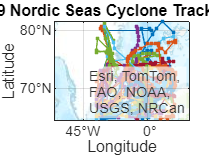

j = max(NordicCandidates2019.track_id);

for c = 0:j
    lat3 = NordicCandidates2019.lat(NordicCandidates2019.track_id == c);
    lon3 = NordicCandidates2019.lon(NordicCandidates2019.track_id == c);
    geoplot(lat3,lon3,'.-')
    geolimits([61 81],[-36 0])
    hold on
end
geobasemap('topographic')
title('2019 Nordic Seas Cyclone Tracks- ERA5')

## Exporting the figure

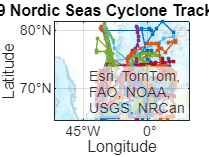

exportgraphics(gca,"NordicERA52019.png","Resolution",300)

## Monthly plots

% month1 = NordicCandidates((month=1),:)
% for month1 = 1:12
%     for c = 0:j
%         lat3 = NordicCandidates.lat(NordicCandidates.track_id == c);
%         lon3 = NordicCandidates.lon(NordicCandidates.track_id == c);
%         geoplot(lat3,lon3,'.-')
%         geolimits([61 81],[324 360]) % FIX THIS
%         geobasemap('colorterrain')
%         title(['month',num2str(month),'tracks'])
%     end
% end

% for c = 0:j
%     switch NordicCandidates.month 
%         case 1
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 2
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 3
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 4
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 5
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 6
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 7
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 8
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 9
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 10
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 11
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 12
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%     end
% end

## Defining tables for each month's data

Jan = NordicCandidates2019(NordicCandidates2019.month == 1, :);
Feb = NordicCandidates2019(NordicCandidates2019.month == 2, :);
Mar = NordicCandidates2019(NordicCandidates2019.month == 3, :);
Apr = NordicCandidates2019(NordicCandidates2019.month == 4, :);
May = NordicCandidates2019(NordicCandidates2019.month == 5, :);
Jun = NordicCandidates2019(NordicCandidates2019.month == 6, :);
Jul = NordicCandidates2019(NordicCandidates2019.month == 7, :);
Aug = NordicCandidates2019(NordicCandidates2019.month == 8, :);
Sep = NordicCandidates2019(NordicCandidates2019.month == 9, :);
Oct = NordicCandidates2019(NordicCandidates2019.month == 10, :);
Nov = NordicCandidates2019(NordicCandidates2019.month == 11, :);
Dec = NordicCandidates2019(NordicCandidates2019.month == 12, :);

## Monthly plots

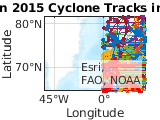

k = max(Jan.track_id);
for d = 0:k
    latj = Jan.lat(Jan.track_id == d);
    lonj = Jan.lon(Jan.track_id == d);
    geoplot(latj,lonj,'.- red')
    geolimits([61 81],[324 20])
    hold on
end
geobasemap('topographic')
title('Jan 2015 Cyclone Tracks in ERA5')

## Masking lat/lon values into -180 - 180

% for lat in 